# �频域实验

## 一、系统辨识建模

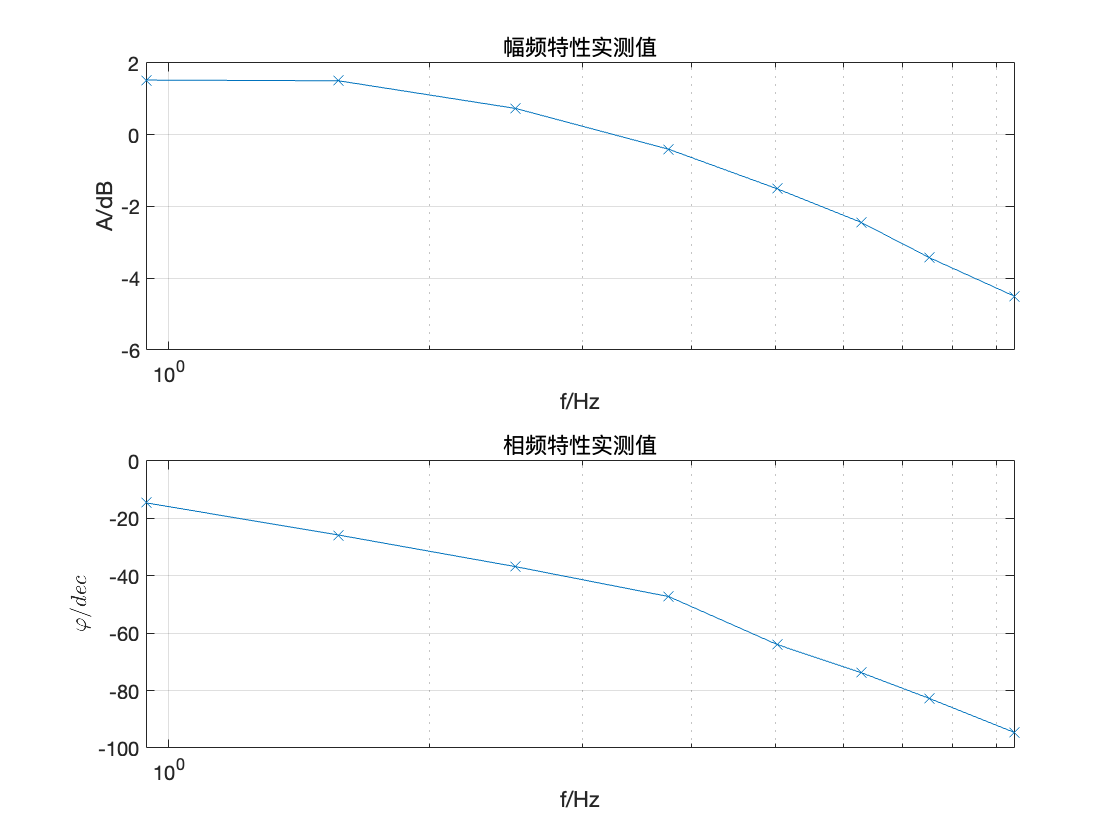

%读取实验室获得的频域数据
sheets=sheetnames("FrequentDomain.xlsx");
%选取俯仰通道数据进行建模
data=readmatrix("FrequentDomain.xlsx","Sheet",sheets(1));
freq=data(:,1);%原数据单位为Hz
A=data(:,2);%原数据单位为dB
phi=data(:,3);
figure();
subplot(2,1,1);
semilogx(freq,A,'x-');
xlabel("f/Hz");
ylabel("A/dB");
title("幅频特性实测值")
grid on
subplot(2,1,2);
semilogx(freq,phi,'x-');
title("相频特性实测值")
xlabel("f/Hz");
ylabel("$\varphi/dec$","Interpreter","latex")
grid on